clear 
clc

addpath '.\INM'
addpath '.\SD'
addpath '.\FR'
addpath '.\functions'

load('forcing_terms.mat')
load('test_functions2.mat')
load('myFunctions.mat')

%Armijo
c1 = 1e-4;
rho = 0.5;
btmax = 50;
alpha0 = 5;

%Step for finite differences
h = 1e-8;

%Problem definition
n = 1000;
x0 = x13(n);
f = f13;
gradf = gf13;
Hessf = 0;

kmax = 10000;
tolgrad = 1.0E-6;
toldiffgrad = 1e-12;

% max number of iterations for the pcg
pcg_maxit = 200;

run_newton = true;
run_steepest = true;
run_fletcher = true;

## Run Steepest Descent

if run_steepest
    tic
    disp('***Steepest Descent: start***')
    [xk_sd, fk_sd, gradfk_norm_sd, k_sd, xseq_sd, btseq_sd, fseq_sd, gfseq_sd] = ... 
        steepest_desc_bt(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax);
    
    disp('***Steepest Descent: finished')
    toc
    disp('***SD: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_sd)])
    disp(['f(xk): ', mat2str(fk_sd)])
    disp(['gradf(xk): ', mat2str(gradfk_norm_sd)])
    disp(['N of iterations: ', num2str(k_sd), '/', num2str(kmax), ';'])
    disp(['fseq: ', mat2str(fseq_sd)])
    disp(['gfseq: ', mat2str(gfseq_sd)])
    
    disp('****')
else
    disp("SD Method not runned")
end

***Steepest Descent: start***


Iteration 1 gf_norm: 11.822747
Iteration 2 gf_norm: 10.746042
Iteration 3 gf_norm: 10.400540
Iteration 4 gf_norm: 10.266498
Iteration 5 gf_norm: 10.211281
Iteration 6 gf_norm: 10.188004
Iteration 7 gf_norm: 10.178100
Iteration 8 gf_norm: 10.173868
Iteration 9 gf_norm: 10.172057
Iteration 10 gf_norm: 0.000679
Iteration 11 gf_norm: 0.000170
Iteration 12 gf_norm: 0.000042
Iteration 13 gf_norm: 0.000011
Iteration 14 gf_norm: 0.000003
Iteration 15 gf_norm: 0.000001


***Steepest Descent: finished


Elapsed time is 0.031514 seconds.


***SD: results


*******


xk: [-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.04793619571109e-08;1.04793619571109e-08;-1.047

f(xk): 1.09817027028142e-13


gradf(xk): 6.62773044195795e-07


N of iterations: 15/10000;


fseq: [52.5560259533575 40.8920690878424 37.5831324866343 36.353949145628 35.8563053909716 35.6480416233289 35.5596893743204 35.5219922293415 35.5058688191662 1.1515150501403e-07 7.19696870998959e-09 4.49810542822836e-10 2.81131589196983e-11 1.75707243245222e-12 1.09817027028142e-13]


gfseq: [11.8227473472908 10.7460420551542 10.4005403699225 10.2664981309926 10.2112805991826 10.1880044990877 10.1780997616966 10.1738682029086 10.1720573170818 0.00067867961257195 0.000169669899582764 4.24174748331855e-05 1.06043687072123e-05 2.65109217678445e-06 6.62773044195795e-07]


****


## Run Fletcher Reeves

if run_steepest
    tic
    disp('***Fletcher Reeves: start***')
    [xk_fr, fk_fr, gradfk_norm_fr, k_fr, xseq_fr, btseq_fr, fseq_fr, gfseq_fr] = ... 
        fletcher_reeves(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax);
    
    disp('***Fletcher Reeves: finished')
    toc
    disp('***FR: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_fr)])
    disp(['f(xk): ', mat2str(fk_fr)])
    disp(['gradf(xk): ', mat2str(gradfk_norm_fr)])
    disp(['N of iterations: ', num2str(k_fr), '/', num2str(kmax), ';'])
    disp(['fseq: ', mat2str(fseq_fr)])
    disp(['gfseq: ', mat2str(gfseq_fr)])
    
    disp('****')
else
    disp("FR Method not runned")
end

***Fletcher Reeves: start***


Iteration 1 gf_norm: 11.822747
Iteration 2 gf_norm: 9.136919
Iteration 3 gf_norm: 2.639033
Iteration 4 gf_norm: 0.317894
Iteration 5 gf_norm: 0.035584
Iteration 6 gf_norm: 0.004465
Iteration 7 gf_norm: 0.000486
Iteration 8 gf_norm: 0.000063
Iteration 9 gf_norm: 0.000007
Iteration 10 gf_norm: 0.000001


***Fletcher Reeves: finished


Elapsed time is 0.034192 seconds.


***FR: results


*******


xk: [-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.39674569482681e-08;1.39674569482681e-08;-1.396

f(xk): 1.95089853601721e-13


gradf(xk): 8.83379541537426e-07


N of iterations: 10/10000;


fseq: [52.5560259533575 27.1342064193972 1.79567475827025 0.0252831166451516 0.000316561199316362 4.98319710607368e-06 5.89776677200562e-08 9.8715342684102e-10 1.06540251372583e-11 1.95089853601721e-13]


gfseq: [11.8227473472908 9.13691895710688 2.63903327565864 0.317893671245932 0.0355840919819308 0.00446461453277623 0.000485706361832853 6.28379957274944e-05 6.52810083783869e-06 8.83379541537426e-07]


****


## Run the Newton

if run_newton
%     fterms = @(gradf, x, k) 0.5;
%    fterms = @(gradfk, k) min(0.5, sqrt(norm(gradfk)));
     fterms = @(gradfk, k) min(0.5, norm(gradfk));
    
    % options for finite differences
    FDgrad = 'c';
    FDHess = 'fw';
    
    disp('***NEWTON F.D. options***')
    disp(['FDgrad: ', FDgrad])
    disp(['FDHess: ', FDHess])
    
    disp('***Newton: start***')
    tic
    [xk, fk, gradfk_norm, k, xseq, btseq, fseq, gfseq] = ...
        innewton_general(x0, f, gradf, Hessf, kmax, ...
        tolgrad, toldiffgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);
    
    disp('***IN. newton: finished')
    toc
    disp('***newton: results')
    disp('*******')
    disp(['xk: ', mat2str(xk)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k), '/', num2str(kmax), ';'])
    disp(['fseq: ',mat2str(fseq)])
    disp(['gfseq: ',mat2str(gfseq)])

    disp('****')
else
    disp("Newton Method not runned")
end

***NEWTON F.D. options***


FDgrad: c


FDHess: Jfw


***Newton: start***


Array indices must be positive integers or logical values.

Error in innewton_general (line 106)
            Hessfk = Hessf(xk);

disp('===========================================================================================================================================================================')

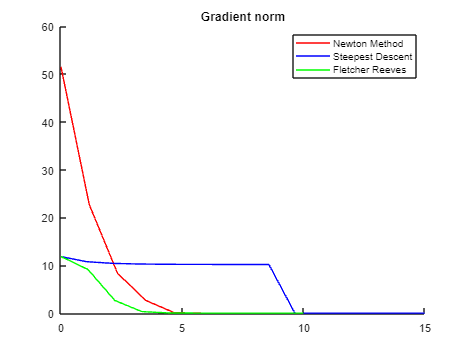


figure(1);
hold on;
title("Gradient norm")
plot(linspace(0,k,k), gfseq, "r")
plot(linspace(0,k_sd,k_sd), gfseq_sd, "b")
plot(linspace(0,k_fr,k_fr), gfseq_fr, "g")
legend(["Newton Method", "Steepest Descent", "Fletcher Reeves"])
hold off

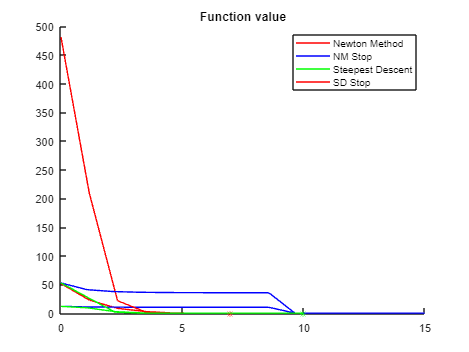

figure(3);
hold on;
title("Function value")
plot(linspace(0,k,k), fseq, "r")
plot(k, fseq(k), "*r")
plot(linspace(0,k_sd,k_sd), fseq_sd, "b")
plot(k_sd, fseq_sd(k_sd), "*b")

plot(linspace(0,k_fr, k_fr), fseq_fr, "g")
plot(k_fr, fseq_fr(k_fr), "*g")
legend("Newton Method","NM Stop", "Steepest Descent", "SD Stop")
hold off;